 Generate 1000 random numbers in [0, 1] and obtain an exponential random variable with mean 5, representing the inter-arrival times of packets to a buffer. Then plot the probability density function of this random variable and determine the mean and variance. Subsequently obtain a Poisson random variable for the number of packet arrivals and plot the probability mass function. Similarly, determine the mean and variance.

`Step-1: Random Number Generation[0 to 1].`

clc
clear all
L_limit=0

L_limit = 0

U_limit=1

U_limit = 1

total=1000

total = 1000

R=L_limit+(U_limit-L_limit)*rand(total,1)

R =     0.8147
    0.9058
    0.1270
    0.9134
    0.6324
    0.0975
    0.2785
    0.5469
    0.9575
    0.9649


Bin=50;
X=histogram(R,Bin)

X =   Histogram with properties:

             Data: [1000×1 double]
           Values: [12 18 20 17 27 29 25 19 27 27 15 20 21 19 21 19 18 16 13 22 17 27 23 17 23 14 27 22 14 20 17 20 28 26 24 15 20 26 22 22 22 14 16 16 14 20 20 20 11 18]
          NumBins: 50
         BinEdges: [1×51 double]
         BinWidth: 0.0200
        BinLimits: [0 1]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


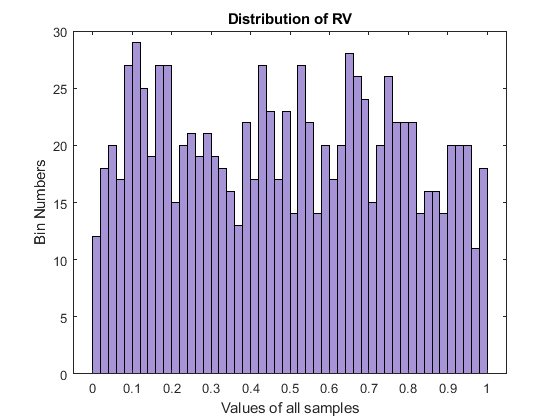

X =   Histogram with properties:

             Data: [1000×1 double]
           Values: [12 18 20 17 27 29 25 19 27 27 15 20 21 19 21 19 18 16 13 22 17 27 23 17 23 14 27 22 14 20 17 20 28 26 24 15 20 26 22 22 22 14 16 16 14 20 20 20 11 18]
          NumBins: 50
         BinEdges: [1×51 double]
         BinWidth: 0.0200
        BinLimits: [0 1]
    Normalization: 'count'
        FaceColor: [0.4200 0.3000 0.7300]
        EdgeColor: [0 0 0]

  Show all properties


xlabel('Values of all samples');
ylabel('Bin Numbers');
title('Distribution of RV') 
X.FaceColor = [.42 .3 .73]


m_1 = 0;
for count_1=1:total
    m_1=m_1+R(count_1);
end

Mean_R=(m_1/total)  %Raw code of Mean

Mean_R = 0.4888

Var_R=sum((R(1:end)-sum(R(1:end))./length(R)).^2)/(length(R)-1) %Raw code of Variance

Var_R = 0.0802



Mean_R1 =mean(R)  %Using Matlab function

Mean_R1 = 0.4888

Var_R1 =var(R)    %Using Matlab function

Var_R1 = 0.0802

Above function can generate 1000 random numbers between [0] to [1 ] with their Mean along with Variance and plot histogram with all samples and number of Bins.

***Step-2: Exponential conversion from RV(Random Variable).***

Now, we have to obtain an exponential random variable with mean 5 and representing the inter-arrival times of packets to a buffer.

From the formula of Exponential RV, we know: 

# FX(x) = 1-*e*^{-$\lambda$*x}*...(i)

As we have taken random variables from 0 to 1 and PDF also operates between 0 to 1. We can consider to use our RV  as a function of PDF(Fx).

# FX(x) = R

Now, if we put this value to equation (i), it will become:

   FX(x) = 1-*e*^{-$\lambda$**x*} 

  >    R = 1 - *e*^{-$\lambda$**x*} 

  >    *e*^{-$\lambda$**x*}  = 1 - R

  >   -$\lambda$**x* = log( 1- R)        % 'log' in both sides. %

# ** x = -(1/**$\lambda$**)*log(1-R) **

Here, (1-R) = R   %Because it varies from 1 to 0.%

Now, It's give in the question that we need to generate a set where mean is 5. So, 1/Lamda =5.

# **x = -(1/0.2)*log(R) **

mean_x=5;
x = -((mean_x)*log(R))

x =     1.0245
    0.4947
   10.3184
    0.4530
    2.2915
   11.6374
    6.3917
    3.0176
    0.2171
    0.1787


Bin=50;
%x1=x/1000;
[y1,y2]=hist(x,Bin)     %Histogram plot of PDF.

y1 =    120   121   119    83    77    72    50    43    43    36    29    36    23    24    27    19    13     8    11     9     7     3     7     4     2     2     2     2     1     1     1     0     1     1     0     1     0     0     0     0     0     0     0     0     1     0     0     0     0     1


y2 =     0.3804    1.1360    1.8917    2.6474    3.4030    4.1587    4.9143    5.6700    6.4257    7.1813    7.9370    8.6927    9.4483   10.2040   10.9596   11.7153   12.4710   13.2266   13.9823   14.7379   15.4936   16.2493   17.0049   17.7606   18.5163   19.2719   20.0276   20.7832   21.5389   22.2946   23.0502   23.8059   24.5615   25.3172   26.0729   26.8285   27.5842   28.3399   29.0955   29.8512   30.6068   31.3625   32.1182   32.8738   33.6295   34.3851   35.1408   35.8965   36.6521   37.4078


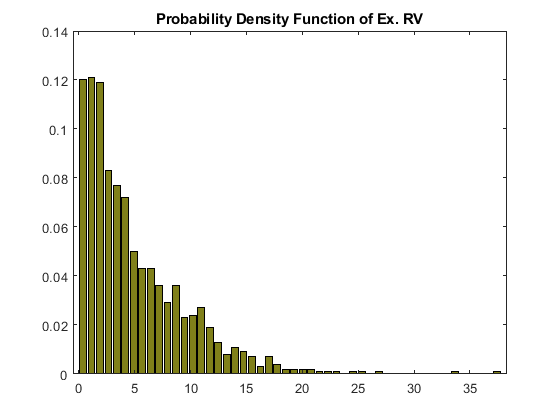

l_1 =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0.5000 0.5000 0.1000]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1×50 double]
        YData: [1×50 double]

  Show all properties


l_1=bar(y2,y1/1000);    %Normalizing y axis.
%x2=histogram(x1,Bin)
title('Probability Density Function of Ex. RV')
l_1.FaceColor = [.5 0.5 .1]

E=(histcounts(x))/total

E =     0.3150    0.2240    0.1440    0.0960    0.0780    0.0630    0.0280    0.0220    0.0140    0.0050    0.0040    0.0020    0.0020    0.0010         0         0    0.0010         0    0.0010


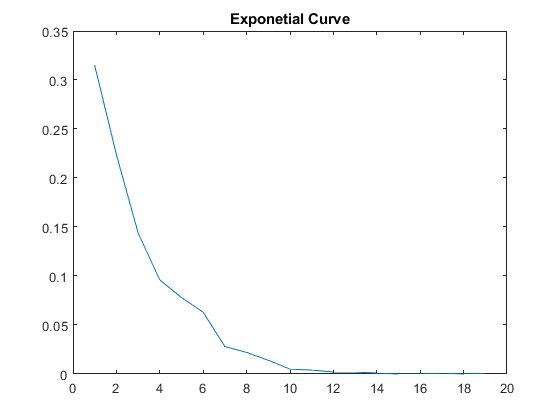

plot(E)
title('Exponetial Curve')


m_2 = 0;
for count_3=1:total
    m_2=m_2+x(count_3);
end
Mean_X=(m_2/total)  %Raw code of Mean

Mean_X = 5.0129

Var_X=sum((x(1:end)-sum(x(1:end))./length(x)).^2)/(length(x)-1) %Raw code of Variance

Var_X = 21.7870



Mean_X1=mean(x)    %%Mean of the function

Mean_X1 = 5.0129

Var_X1=var(x)     %%Variance of the function

Var_X1 = 21.7870

Now, we have calculated Mean and Variance of 1000 exponential random variables. 

# We got Mean ≈ 5 

From the formula, E[X] =1/$\lambda$= 5

So, Both are almost simiar.

# And , We got Variance ≈22

From the formula, E[X]^2 =1/($\lambda$)^2= 25

So, It's also simiar to our calculated value.

***Step-3: Poisson RV generation(PMS)***

It is given in the qustion, When the packets sent the inter arraival time is exponential.

We know,Mean(Lambda)= 5

for, T=20sec.

so, Mean = $\alpha$ =$\mu T$= (1/5)*20=4

and Variance = $\alpha$ = $\mu T$ = (1/5)*20 =4

Now we have to write a code for generating Poisson Random Variables.

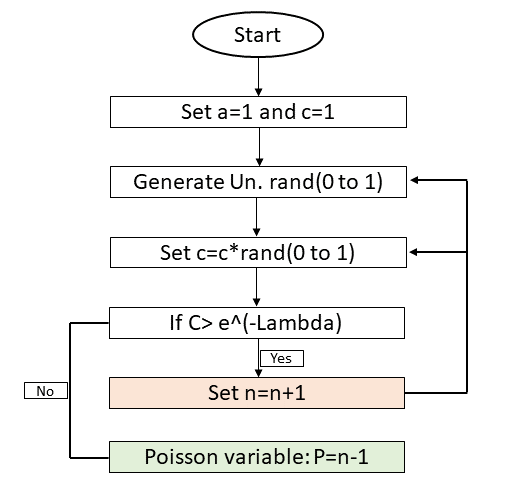

l=4;                                    %Mean
t=1;                                    %Initial value
n=1000;
while t<=n                              %loop starts here[1 to 1000]
    a=1; c=1;                           % 'c' is multiplier and 'a' is number of iteration.
    L_lim=0;                            %Random variable intial point.
    U_lim=1;                            %Random variable final point.
    Random=L_lim+(U_lim-L_lim)*rand;    %Random variable generation.         
    c= c*Random;                        % 'c' multiplies with random number.
    while c >= exp(-l)                  % if this validates, program goes back to step 2 and n+1.
    L_lim=0;                            %if above condition does not validate, it generates, 
    Random=L_lim+(U_lim-L_lim)*rand;    % random number and add with the iteration number
        c = c*Random;       
        a = a+1;                
    end                         
    P(t) = a;
    t=t+1;
end
P                                        %  'P' is the poisson variable.

P =      7     2     5     6     3     3     6     9     6     5     2     8     2     5     9     8     5     6     5     1     5     6     5     4     4     4     3     5     3     7     6     8     7     8     4     5     6     4     7     4     5     3     4     3     3     4     3     7     2     6



Bin=50;
x=histogram(P,Bin) %Plotting Poisson random Variables

x =   Histogram with properties:

             Data: [1×1000 double]
           Values: [8 0 0 0 83 0 0 0 0 132 0 0 0 200 0 0 0 0 179 0 0 0 167 0 0 0 0 104 0 0 0 75 0 0 0 0 29 0 0 0 15 0 0 0 0 6 0 0 0 2]
          NumBins: 50
         BinEdges: [1×51 double]
         BinWidth: 0.2200
        BinLimits: [1 12]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


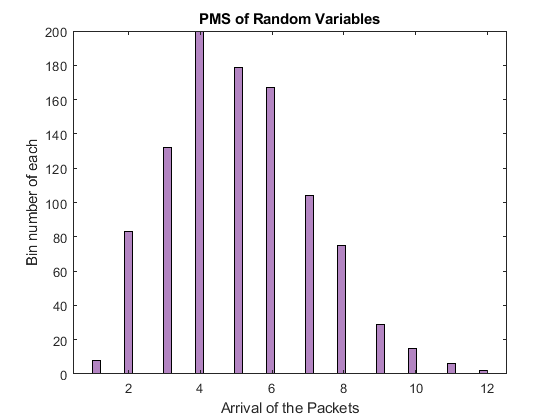

x =   Histogram with properties:

             Data: [1×1000 double]
           Values: [8 0 0 0 83 0 0 0 0 132 0 0 0 200 0 0 0 0 179 0 0 0 167 0 0 0 0 104 0 0 0 75 0 0 0 0 29 0 0 0 15 0 0 0 0 6 0 0 0 2]
          NumBins: 50
         BinEdges: [1×51 double]
         BinWidth: 0.2200
        BinLimits: [1 12]
    Normalization: 'count'
        FaceColor: [0.5000 0.2000 0.6000]
        EdgeColor: [0 0 0]

  Show all properties


xlabel('Arrival of the Packets');
ylabel('Bin number of each');
title('PMS of Random Variables')
x.FaceColor = [0.5 0.2 0.6]



m_3 = 0;
for count_5=1:n
    m_3= m_3 + P(count_5);
end
Mean_P=(m_3/n)  %Raw code of Mean

Mean_P = 5.0960

Var_P=sum((P(1:end)-sum(P(1:end))./length(P)).^2)/(length(P)-1) %Raw code of Variance

Var_P = 4.0088


Mean_P1=mean(P)

Mean_P1 = 5.0960

Variance_P1=var(P)

Variance_P1 = 4.0088

#### Here, Obtained mean is  5 ≈ 4, from formula  E[X]=*Alpha* = 4 . Same as our calculated value.

#### And obtained Variance is 4 ≈ 4. From formula E[X]^2=*Alpha*=4. Same as our calculated value.

# Let's check our proagram for diffrent arrival time.

Let, T=100sec.

so, Mean = $\alpha$ =$\mu T$= (1/5)*100=20

and Variance = $\alpha$ = $\mu T$ = (1/5)*100 =20

l1=20;                                   %Mean
t1=1;                                    %Initial value
n1=1000;
while t1<=n1                             %loop starts here[1 to 1000]
    a1=1; c1=1;                          % 'c1' is multiplier and 'a1' is number of iteration.
    L_lim1=0;                            %Random variable intial point.
    U_lim1=1;                            %Random variable final point.
    Random1=L_lim1+(U_lim1-L_lim1)*rand; %Random variable generation.         
    c1= c1*Random1;                      % 'c1' multiplies with random number.
    while c1 >= exp(-l1)                 % if this validates, program goes back to step 2 and n1+1.
    L_lim1=0;                            %if above condition does not validate, it generates, 
    Random1=L_lim1+(U_lim1-L_lim1)*rand; % random number and add with the iteration number
        c1 = c1*Random1;       
        a1 = a1+1;                
    end                         
    P1(t1) = a1;
    t1=t1+1;
end
P1                                        %  'P1' is the poisson variable.

P1 =     16    24    24    20    19    24    17    17    28    24    23    20    28    16    18    25    19    18    11    15    17    25    26    30    21    21    27    23    24    18    25    26    20    20    25    20    28    19    20    17    19    27    17    23    23    25    12    23    16    20



Bin=50;
x1=histogram(P1,Bin) %Plotting Poisson random Variables

x1 =   Histogram with properties:

             Data: [1×1000 double]
           Values: [3 4 0 6 0 10 0 16 0 27 0 35 60 0 68 0 84 0 92 0 93 0 88 0 81 83 0 57 0 46 0 42 0 34 0 32 0 13 9 0 6 0 6 0 1 0 3 0 0 1]
          NumBins: 50
         BinEdges: [1×51 double]
         BinWidth: 0.5400
        BinLimits: [9 36]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


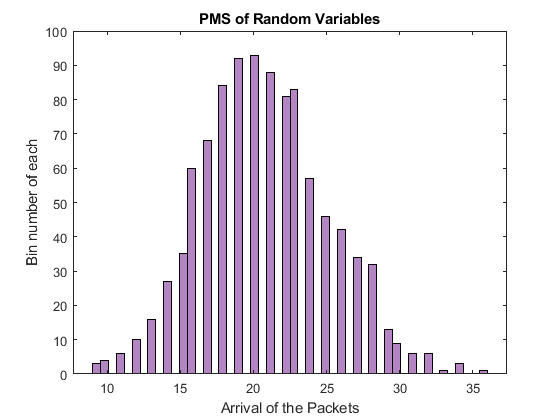

x1 =   Histogram with properties:

             Data: [1×1000 double]
           Values: [3 4 0 6 0 10 0 16 0 27 0 35 60 0 68 0 84 0 92 0 93 0 88 0 81 83 0 57 0 46 0 42 0 34 0 32 0 13 9 0 6 0 6 0 1 0 3 0 0 1]
          NumBins: 50
         BinEdges: [1×51 double]
         BinWidth: 0.5400
        BinLimits: [9 36]
    Normalization: 'count'
        FaceColor: [0.5000 0.2000 0.6000]
        EdgeColor: [0 0 0]

  Show all properties


xlabel('Arrival of the Packets');
ylabel('Bin number of each');
title('PMS of Random Variables')
x1.FaceColor = [0.5 0.2 0.6]



m_31 = 0;
for count_51=1:n1
    m_31= m_31 + P1(count_51);
end
Mean_P11=(m_31/n1)  %Raw code of Mean

Mean_P11 = 20.7590

Var_P11=sum((P1(1:end)-sum(P1(1:end))./length(P1)).^2)/(length(P1)-1) %Raw code of Variance

Var_P11 = 18.9659


Mean_P1=mean(P1)  %Matlab function of Mean.

Mean_P1 = 20.7590

Variance_P1=var(P1) %Matlab function of Variance.

Variance_P1 = 18.9659

#### Here, Obtained mean is  20.7 ≈ 20, from formula  E[X]=*Alpha* = 20 . Same as our calculated value.

#### And obtained Variance is 19 ≈ 20. From formula E[X]^2=*Alpha*=20. Same as our calculated value.

# **Discussion:**

This project can be done by using default function but we have used raw scripting to understand the problem deeply. From this project we have understood how to generate exponential & poisson random variable by writing raw code using MATLAB. The main focus of this project was also determine theoratical formulas by judging the properties of Random variable that we have generated. We have checked our calculated values with formulated values by comparing Mean and Variance to prove formulas of Textbook.